clearvars; close('all')

indir       ='C:\ecoSUB C3 GUI\Logs';           % set file path 
testdate    ='20210806';                        % enter test date
imei        ='300434062118160' ;                % unique to each instrument
infolder    =fullfile(indir,testdate,imei);     % build file path
state_file  = dir([infolder filesep '*_ecosub_state_v2.csv']); % list relevant files

% choose some quality control parameters
lat_lim     = [56.4 56.5];  % geographical exclusion
lon_lim     = [-5.5 -5.3];  % geographical exclusion
dep_lim     = 0.5;          % depth exclusion

for kk = 1:numel(state_file)
   
    statev2=readtable([infolder filesep state_file(kk).name],"PreserveVariableNames",false);

Extract data and make conversion

    D       =statev2.Depth;    
    C       =statev2.Conductivity;
    T       =statev2.Temperature;
    Lat     =statev2.Latitude;
    Lon     =statev2.Longitude;
    
    q1      = D<=dep_lim;
    q2      =Lat>=lat_lim(2) | Lat<=lat_lim(1);
    q3      =Lon>=lon_lim(2) | Lon<=lon_lim(1);
    ix      = q1 | q2 | q3;

    D(ix)=NaN;
    C(ix)=NaN;
    T(ix)=NaN;
    Lat(ix)=NaN;
    Lon(ix)=NaN;
    
    SP      = gsw_SP_from_C(C,T,D);

    Time    =statev2.Time;
    mtime   =datenum(datetime(Time, 'convertfrom','posixtime'));
    Speed   =statev2.ForwardSpeed;
    Heading =statev2.Heading;
    Pitch   =statev2.Pitch;
    Roll    =statev2.Roll;
    RPM     =statev2.RPM;
    B1volt  =statev2.Battery1Volt;
    B1crnt  =statev2.Battery1Current;
    Rangle  =statev2.RudderAngle;
    
    mission =char(statev2.MissionName(1))

mission = 'Ardmucknish-test-dive-spiral-060821'

mission = 'Ardmucknish-test-dive-spiral-060821'

mission = 'Ardmucknish-test-dive-spiral-060821'

mission = 'Ardmucknish-test-dive-spiralRENAME-060821'

mission = 'Ardmucknish-test-dive-spiralRENAME-060821'

mission = 'Ardmucknish-test-dive-track-060821'

mission = 'Ardmucknish-test-spiral_dive-track-060821'

mission = 'Ardmucknish-test-spiral_dive-track-060821'

Plot science data

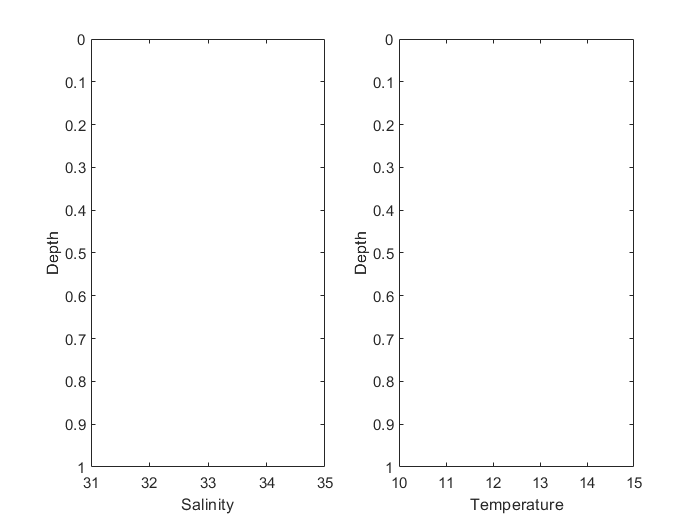

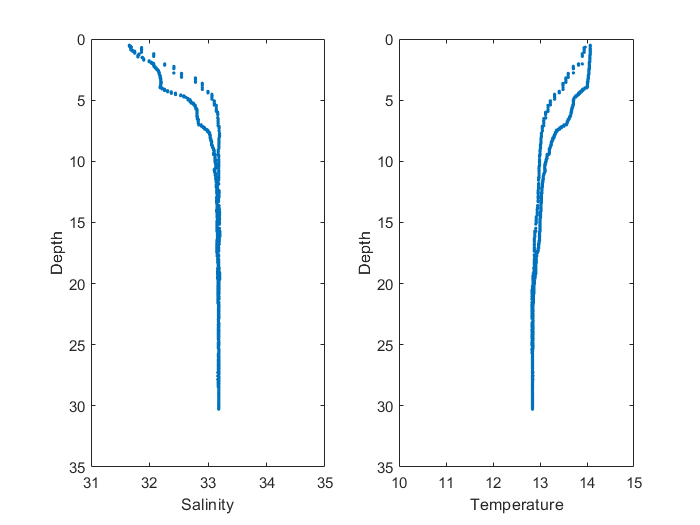

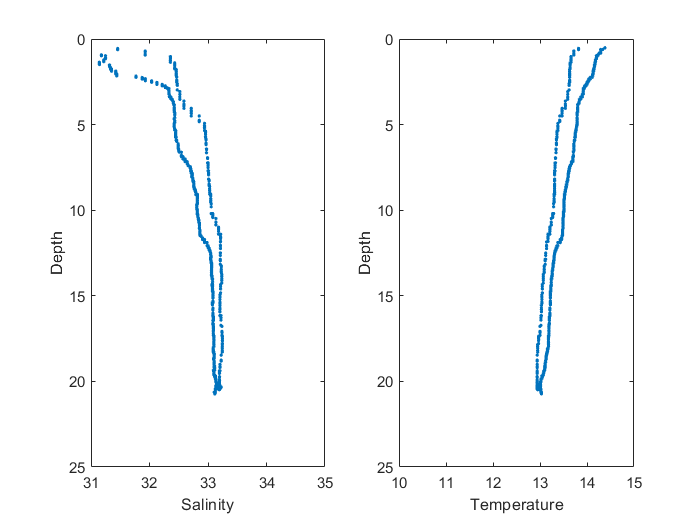

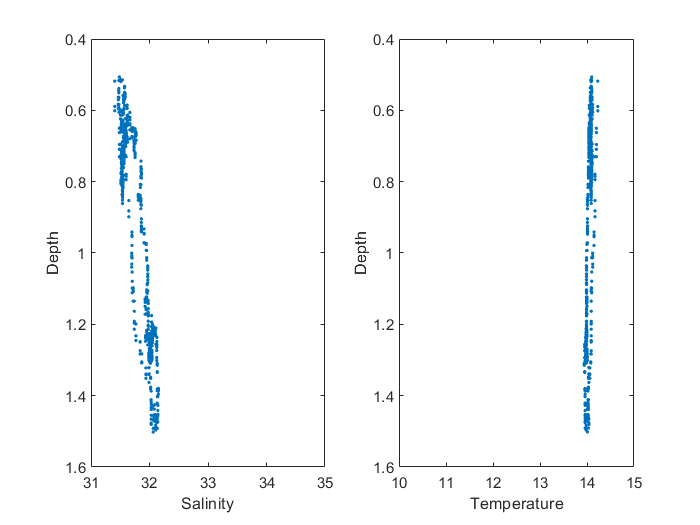


figure;
ax1=subplot(1,2,1);
plot(SP,D,'.');
axis ij; xlim([31 35]);
xlabel('Salinity'); ylabel('Depth');

ax2=subplot(1,2,2);
plot(T,D,'.');
axis ij; xlim([10 15]);
xlabel('Temperature'); ylabel('Depth');

print(gcf, '-dpng',['figures/' char(statev2.MissionName(1)) '-2dplot'])

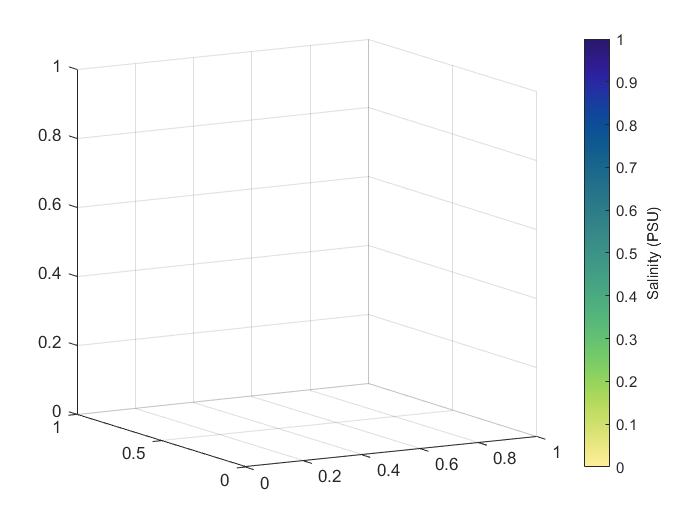

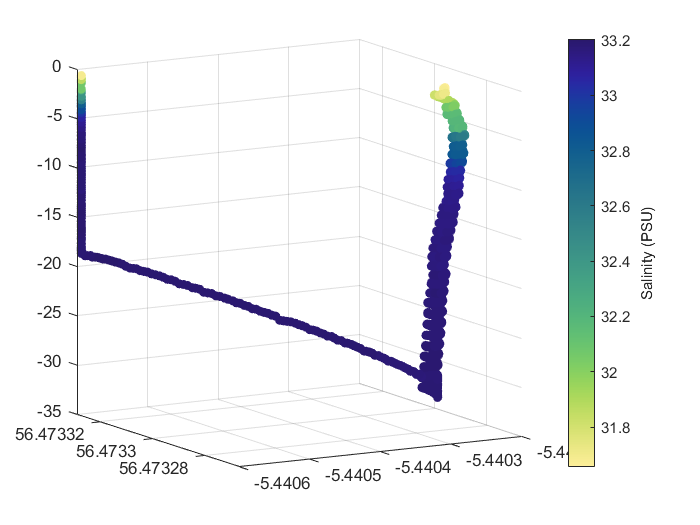

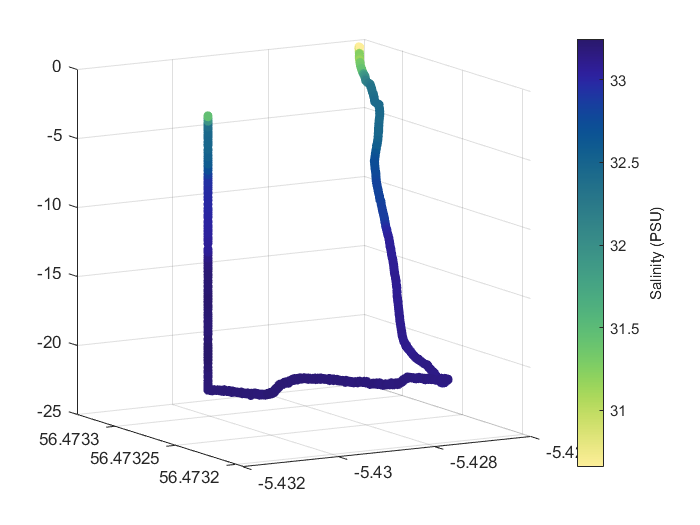

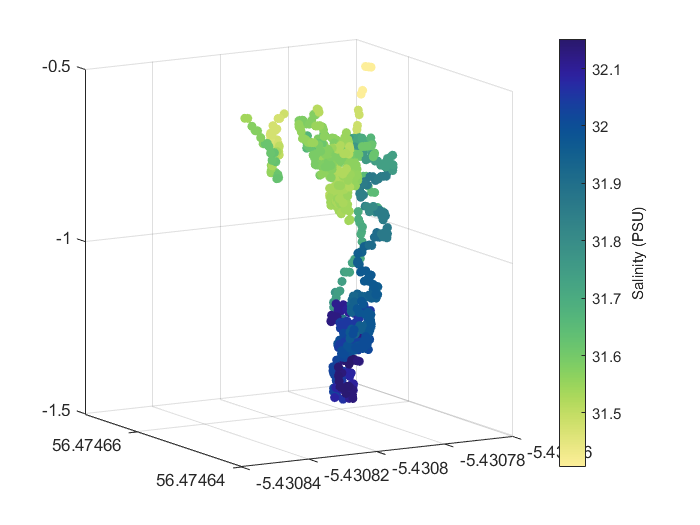


figure;
scatter3(Lon,Lat,D*-1,30,SP,'filled');
sgtitle(statev2.MissionName(1));
view(-30,10)
C=colorbar;
C.Label.String ='Salinity (PSU)';
cmap=cmocean('-Haline');
colormap(cmap);
print(gcf, '-dpng',['figures/' char(statev2.MissionName(1))  '-' datestr(mtime(1),30) '-salinity-3d'])

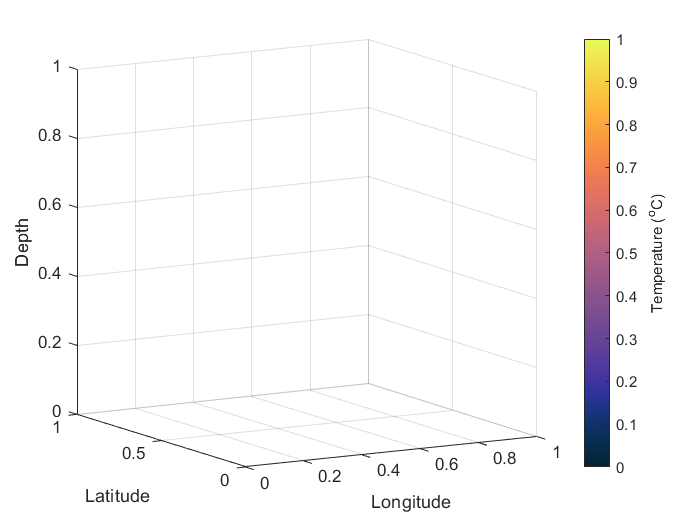

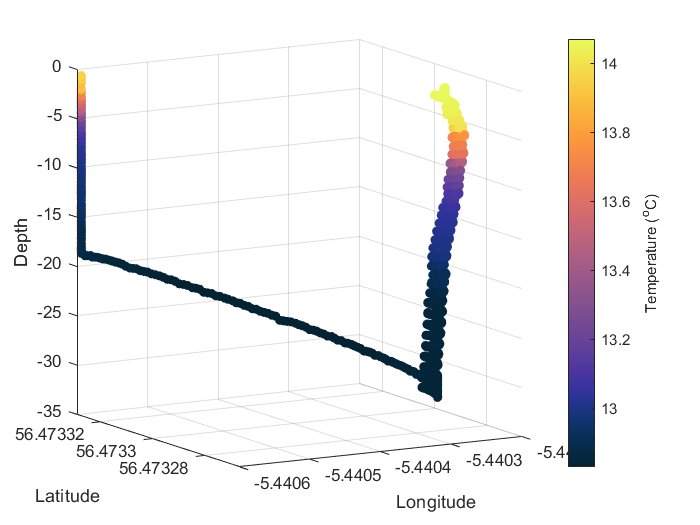

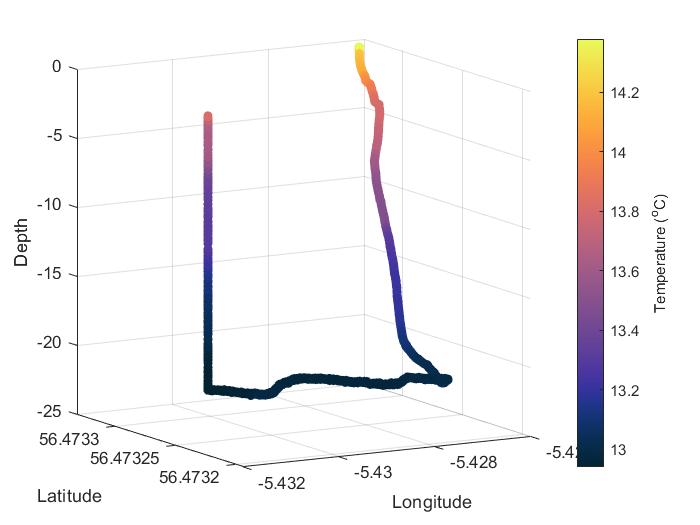

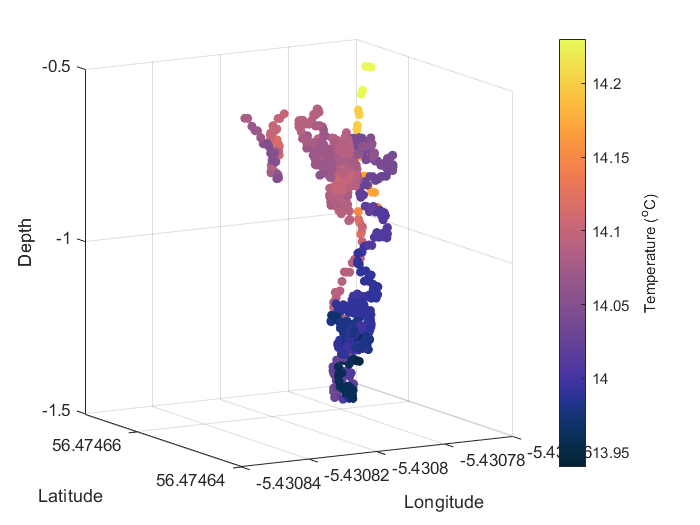


figure;
scatter3(Lon,Lat,D*-1,30,T,'filled');
view(-30,10)
xlabel('Longitude'); ylabel('Latitude'); zlabel('Depth')
C=colorbar;
C.Label.String ='Temperature (^oC)';
cmap=cmocean('Thermal');
colormap(cmap);sgtitle(statev2.MissionName(1));

print(gcf, '-dpng',['figures/' char(statev2.MissionName(1)) '-' datestr(mtime(1),30) '-temperature-3dplot'])

Plot vehicle diagnostics

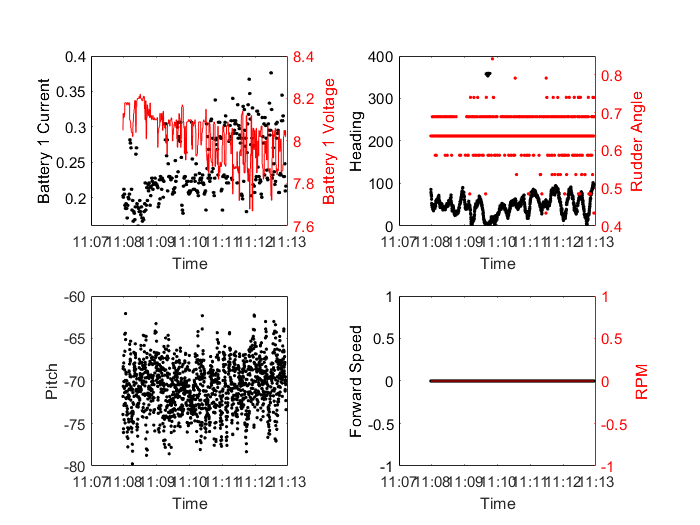

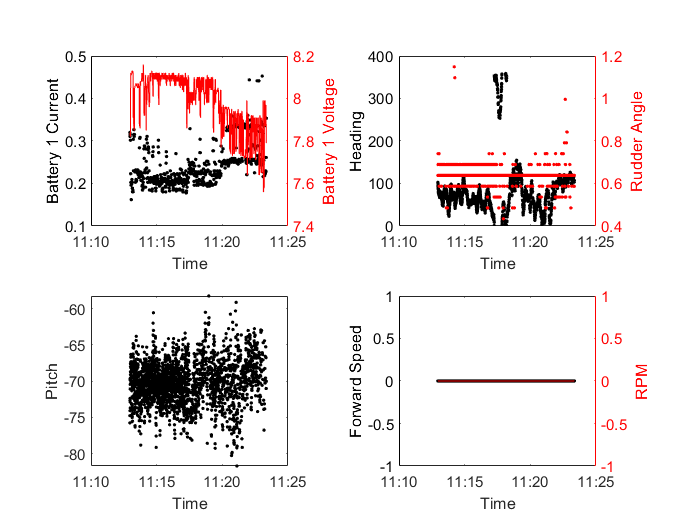

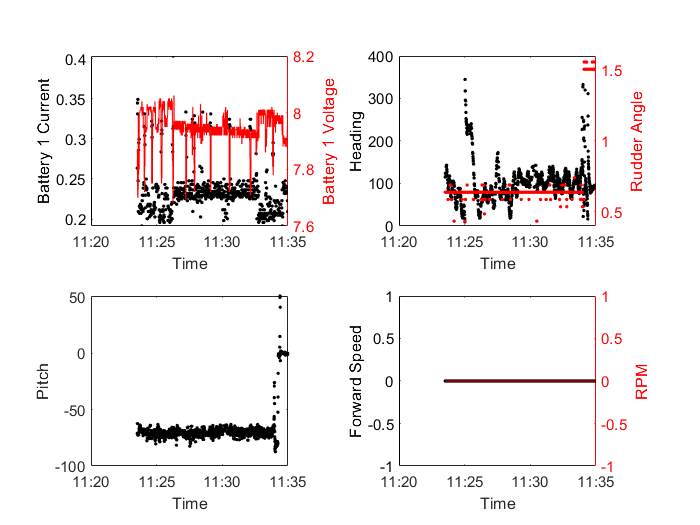

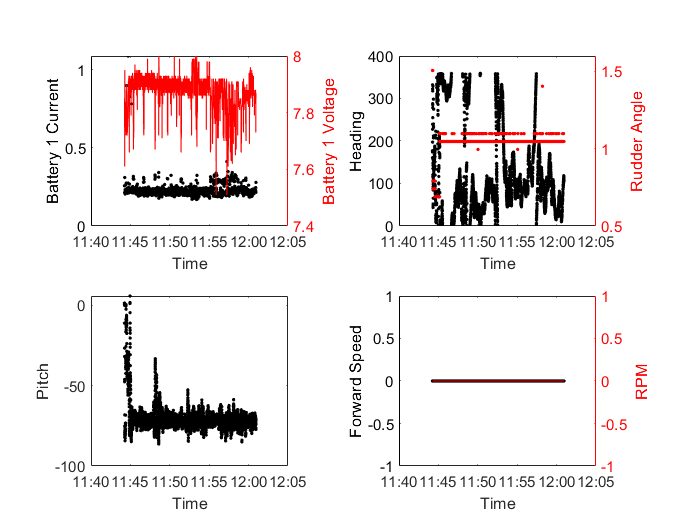

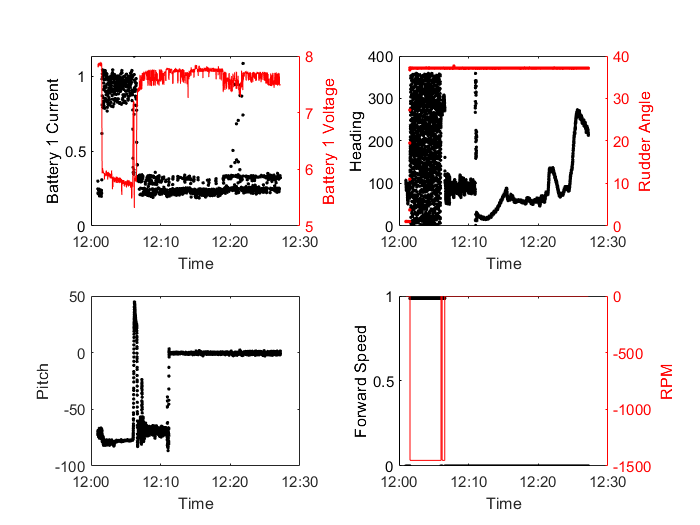

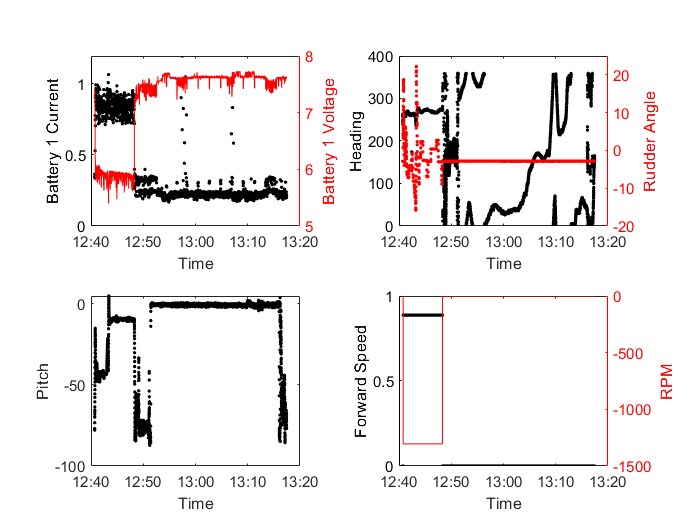

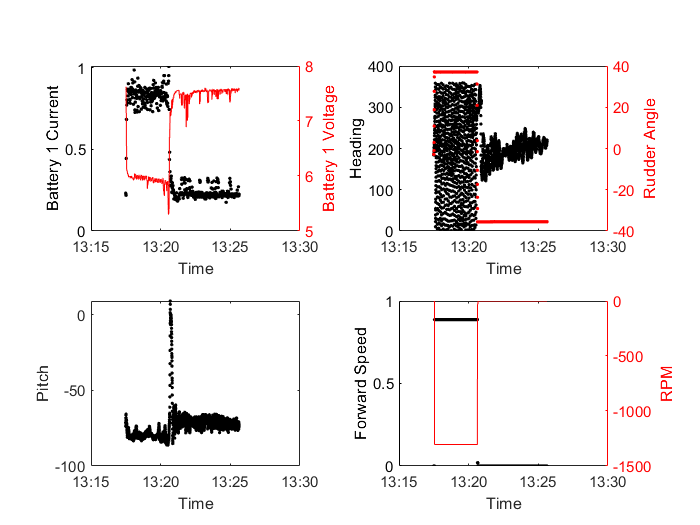

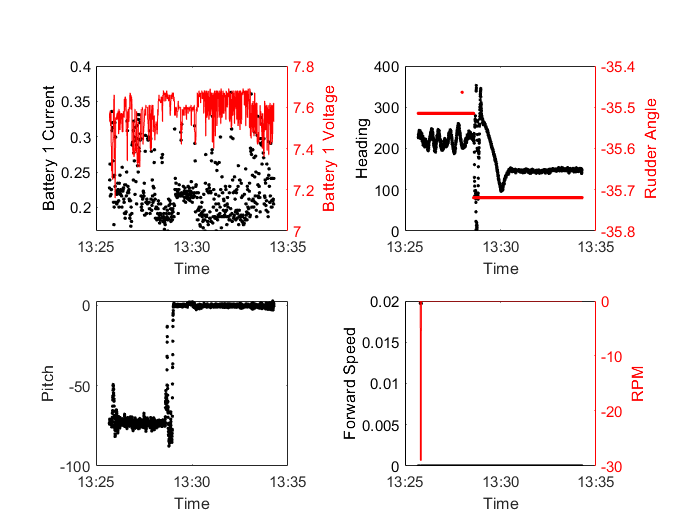

figure;
ax(1)=subplot(2,2,1);
colororder({'k','r'})
yyaxis left
plot(mtime,B1crnt,'k.')
ylabel('Battery 1 Current');
yyaxis right
plot(mtime,B1volt,'r-')
ylabel('Battery 1 Voltage');

ax(2)=subplot(2,2,2);
colororder({'k','r'})
yyaxis left
plot(mtime,Heading,'k.')
ylabel('Heading');
yyaxis right
plot(mtime,Rangle,'r.')
ylabel('Rudder Angle');

ax(3)=subplot(2,2,3);
plot(mtime,Pitch,'.')
ylabel('Pitch');

ax(4)=subplot(2,2,4);
colororder({'k','r'})
yyaxis left
plot(mtime,Speed,'k.')
ylabel('Forward Speed');
yyaxis right
plot(mtime,RPM,'-r');
ylabel('RPM');

for ii=1:numel(ax)
    ax(ii);
    xlabel(ax(ii),'Time');
    datetick(ax(ii),'x');
end

sgtitle(statev2.MissionName(1));

print(gcf,'-dpng',['figures/' char(statev2.MissionName(1)) '_' datestr(mtime(1),30) '_diagnostics']);

end